
close all
close all hidden 
simTime = 60;    % in seconds
updateRate = 2;  % in Hz
scene = uavScenario("UpdateRate",updateRate,"StopTime",simTime); 
x_max = 80;
z_max = 40;


# Create map

addMesh(scene, "Polygon",{[0 0;x_max 0;x_max x_max;0 x_max],[0 0.3]},[1 1 1]);
addMesh(scene, "Polygon",{[0 0;0 x_max;0.3 x_max;0.3 0],[0 z_max]},[0 0 0]);
addMesh(scene, "Polygon",{[0 x_max;x_max x_max;x_max x_max+0.3;0 x_max],[0 z_max]},[0 0 0]);
addMesh(scene, "Polygon",{[x_max x_max;x_max 0;x_max+0.3 0;x_max+0.3 x_max],[0 z_max]},[0 0 0]);
xlim([-11 91])
ylim([-0.0 80.3])
zlim([-0.2 80.2])
object_size = 25;
for n = 1:30
    
    x_size = rand*object_size;
    y_size = rand*object_size;
    z_size = rand*object_size;
    x = 10+rand*(x_max-20);
    y = 10+rand*(x_max-20);
    z_min = abs(rand*z_max-z_size);
    if mod(n,2)==0
        addMesh(scene, "Polygon",{[x-x_size/2 y;x y+y_size/2;x+x_size/2 y;x y-y_size/2],[z_min z_min+z_size]},[rand rand rand]); 
    else
        addMesh(scene, "Polygon",{[x-x_size/2 y;x y+y_size/2;x+x_size/2 y;x y-y_size/2],[0 z_size]},[rand rand rand]); 
    end
    
end



View the created scene in 3D. 

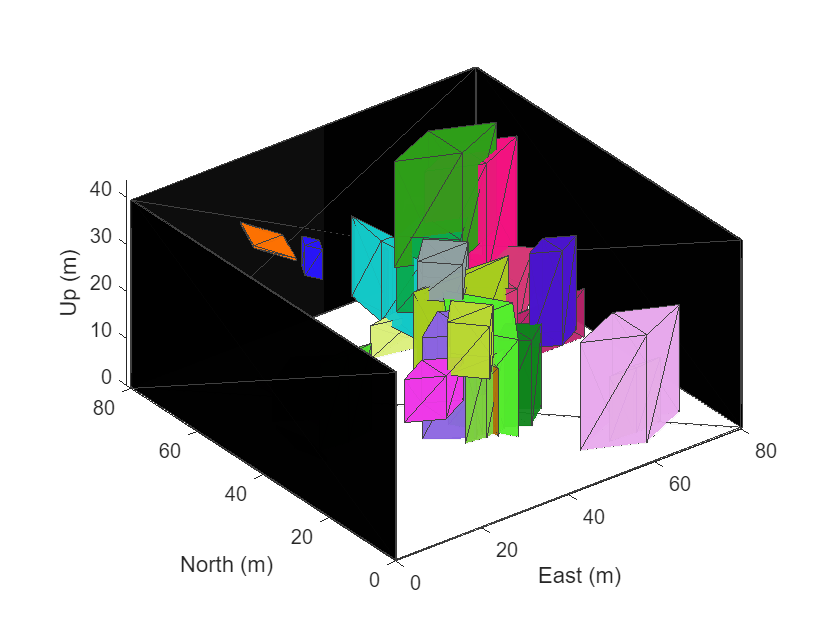

hold off
show3D(scene);
axis equal

## Create Mapping Trajectory

Specify the trajectory that the UAV follows for mapping the environment. Specify waypoints and assign orientation for each waypoint. 

The complete pose vector for UAV is as follows 

`pose = [x y z a b c d]`

`x`, `y` and `z` specify the position of the UAV with respect to the scene's frame of reference. `a`, `b`, `c` and `d` are the parts of the quaternion number that specifies the orientation of the UAV with respect to the scene's reference frame. a is the real part of the quaternion.

% Waypoints 
x = zeros(1,x_max);
y =zeros(1,x_max);
z = z_max*ones(1,length(x)); 

waypoints = [x' y' z']; 

Specify the orientation as Euler angles (in radians) and convert the Euler angles to a quaternion:

orientation_eul = [0 0 0];
orientation_quat = quaternion(eul2quat(orientation_eul)); 
orientation_vec = repmat(orientation_quat,length(x),1);

Specify time vector

 time = 0:(simTime/(length(x)-1)):simTime;

  Generate trajectory from the specified waypoints and orientations using `waypointTrajectory` system object. Specify the reference frame as 'ENU'. 

trajectory = waypointTrajectory("Waypoints",waypoints,"Orientation",orientation_vec, ...
    "SampleRate",updateRate,"ReferenceFrame","ENU","TimeOfArrival",time); 

Specify the initial pose of the UAV

initial_pose = [0 0 z_max 1 0 0 0]; 

## Create UAV Platform 

Create a `uavPlatform` object and update the scene with a mesh of the UAV. 

plat = uavPlatform("UAV",scene,"Trajectory",trajectory,"ReferenceFrame","ENU"); 
updateMesh(plat,"quadrotor",{4},[1 0 0],eye(4)); 

Introduce a 3D lidar into the scene using the `uavLidarPointCloudGenerator` system object. Specify relevant lidar sensor parameters. For example, the lidar in this example has a maximum range of 200 meters, but you can adjust the parameters as needed.

lidarmodel = uavLidarPointCloudGenerator("AzimuthResolution",0.6, ...
    "ElevationLimits",[-90 -20],"ElevationResolution",2.5, ...
    "MaxRange",200,"UpdateRate",2,"HasOrganizedOutput",true);

lidar = uavSensor("Lidar",plat,lidarmodel,"MountingLocation",[0 0 -1],"MountingAngles",[0 0 0]); 

## Simulate Mapping Flight And Map Building

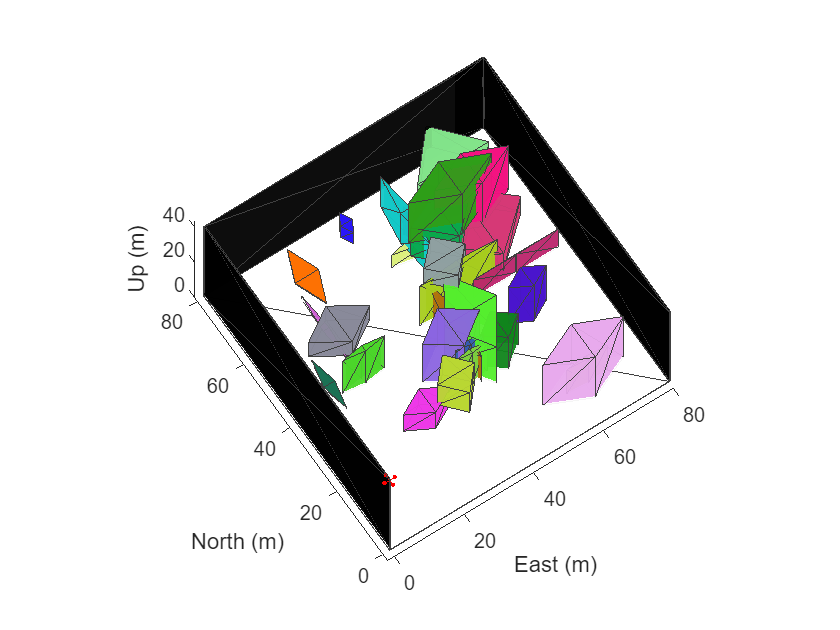

[ax,plotFrames] = show3D(scene);
xlim([-15 80]);
ylim([-15 80]);
zlim([0 80]);
view([-33.6 65.2]); 
axis equal 
hold on

colormap('jet');
ptc = pointCloud(nan(1,1,3));
scatterplot = scatter3(nan,nan,nan,1,[0.3020 0.7451 0.9333],...
    "Parent",plotFrames.UAV.Lidar);
scatterplot.XDataSource = "reshape(ptc.Location(:,:,1), [], 1)";
scatterplot.YDataSource = "reshape(ptc.Location(:,:,2), [], 1)";
scatterplot.ZDataSource = "reshape(ptc.Location(:,:,3), [], 1)";
scatterplot.CDataSource = "reshape(ptc.Location(:,:,3), [], 1) - min(reshape(ptc.Location(:,:,3), [], 1))";
hold off; 


lidarSampleTime = [];
pt = cell(1,((updateRate*simTime) +1)); 
ptOut = cell(1,((updateRate*simTime) +1)); 

Create an occupancy map for a more efficient way to store the point cloud data. Use a minimum resolution of 1 cell per meter.

map3D = occupancyMap3D(1);

Simulate the mapping flight in the scene. Store lidar sensor readings for each simulation step in a cell array after removing invalid points. Insert point clouds into the map using the `insertPointCloud` function. Ensure that the pose vector accounts for sensor offset. 

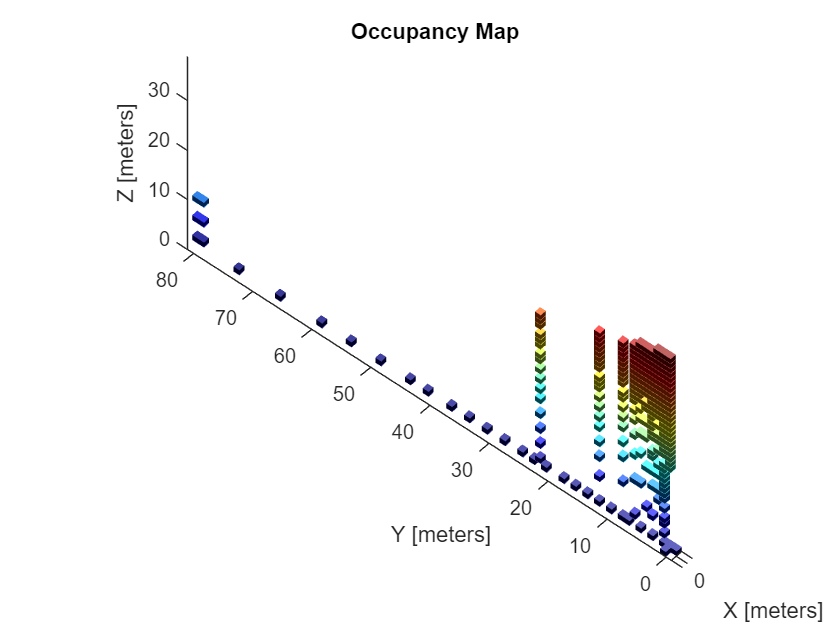

setup(scene); 

ptIdx = 0;
while scene.IsRunning
    ptIdx = ptIdx + 1;
    % Read the simulated lidar data from the scene
    [isUpdated,lidarSampleTime,pt{ptIdx}] = read(lidar);

    if isUpdated
        % Get Lidar sensor's pose relative to ENU reference frame.
        sensorPose = getTransform(scene.TransformTree, "ENU","UAV/Lidar",lidarSampleTime);
        % Process the simulated Lidar pointcloud.
        ptc = pt{ptIdx};
        ptOut{ptIdx} = removeInvalidPoints(pt{ptIdx});
        % Construct the occupancy map using Lidar readings.
        insertPointCloud(map3D,[sensorPose(1:3,4)' tform2quat(sensorPose)],ptOut{ptIdx},500);

        figure(1)
        show3D(scene,"Time",lidarSampleTime,"Parent",ax);
        xlim([-15 80]);
        ylim([-15 80]);
        zlim([0 110]);
        view([-33.6 65.2]);
         
        refreshdata
        drawnow limitrate


        % Waypoints 
        plat.move(sensorPose,)
        x = ones(1,x_max);
        y =ones(1,x_max);
        z = z_max*ones(1,length(x)); 

        waypoints = [x' y' z']; 
        orientation_eul = [0 0 0];
        orientation_quat = quaternion(eul2quat(orientation_eul));
        orientation_vec = repmat(orientation_quat,length(x),1);
        time = 0:(simTime/(length(x)-1)):simTime;
        trajectory = waypointTrajectory("Waypoints",waypoints,"Orientation",orientation_vec, ...
            "SampleRate",updateRate,"ReferenceFrame","ENU","TimeOfArrival",time);

    end
    
    % Show map building real time 
    figure(2)
    show(map3D);
   
    axis equal 
    
    advance(scene);
    updateSensors(scene); 
    
end